p = '/asap3/petra3/gpfs/p07/2022/data/11012618/processed/etna_001_et16tard_a/reco/float_rawBin2';
p='/asap3/petra3/gpfs/p07/2022/data/11012618/processed/etna_068_cse100222g_f/reco/float_rawBin2';
vol = read_images_to_stack(p,1,'*.tif',[],1,0);
n0 = 1;
n1 = size(vol,3);
ndefault = round((n1-n0)/2);
dn = 1;

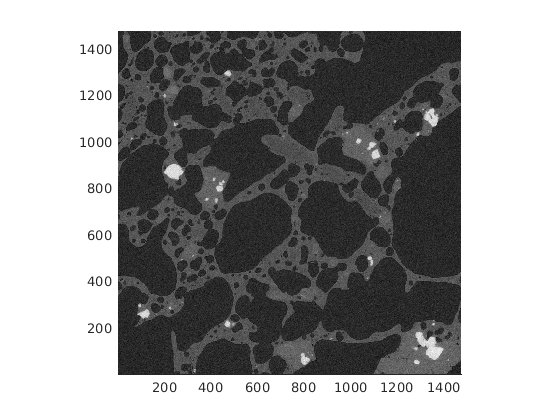

x = round( [0.2 0.8] * (size(vol,1) - 1) + 1);
y = round( [0.2 0.8] * (size(vol,2) - 1) + 1);
xr = x(1):x(2);
yr = y(1):y(2);
if ~exist('h', 'var') || ~isvalid(h)
    im = vol(xr,yr,506);
    imi = uint8(2^8 * normat( im ));
    h = imagesc('CData', imi);
    colormap(gray)
    axis image tight
    hold on
end
z =387;
%im = vol(:,:,z);
%im = normat(im);
%dr = 10;
%dr = [dr, 100-dr] / 100;
%imsc(im)
%img = gpuArray(im);
%hold on
%h = imagesc('CData', im);
%h.Parent.Position = [1 1 100 100];
im = vol(xr,yr,z);
imi = uint8(2^8 * normat(im));
%imagesc('CData', imi)
h.CData = imi;
%set(h.Parent,'Units','normalized','Position',[0 0 1 1]); 
drawnow

%refreshdata

h.Parent.Position